# Simple Model

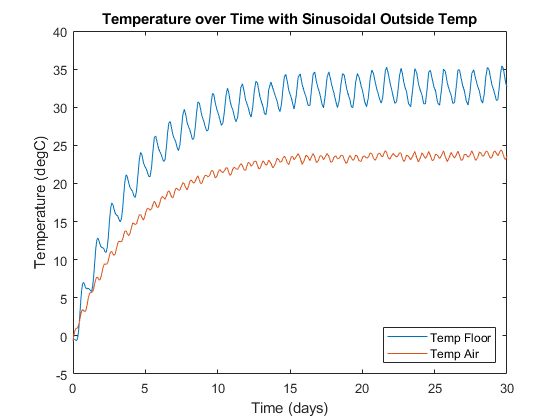

%define constants

k_wall = .04; %W/m-K
%sa_wall = total surface area of wall in contact with internal air
sa_wall = (.2*5) + (5.1*5) + (3*5) + (5.1*5) + (.4*5); %m^2
L_wall = .025; %m

d_floor = 3000; %kg/m^3, based on d for recycled ceramic tile
c_floor = 800; %J/kg-K, based on c for recycled ceramic tile
L_floor = .5; %m %.05:.01:.1;
v_floor = 5.1 * L_floor * 5; %m^3
C_floor = d_floor * v_floor * c_floor; %J/K
sa_floor = 5.1*5; %m^2

sa_window = 2.6*5; %m^2
h_eq_window = .7; %W/m^2-K 

h_in = 15; %W/m^2-K
h_out = 30; %W/m^2-K

%Calculate Resistances, these Rs are defined in doc named
%updatedSimpleModel
R0 = 1/(h_in * sa_floor);

R1 = 1/(h_in * sa_wall);
R2 = L_wall/(k_wall * sa_wall);
R3 = 1/(h_out * sa_wall);

R4 = 1/(h_in * sa_window);
R5 = 1/(h_eq_window * sa_window);
R6 = 1/(h_out * sa_window);

RA = R1 + R2 + R3;
RB = R4 + R5 + R6;

%Equations
t_span = [0 60*60*24*30];

Q_in = @(t) ((-361*cos(pi *t/(12*3600)) + 224*cos(pi * t/(6*3600)) + 210)*sa_window);
T_out_sin = @(t) (-3 + 6*sin((2*pi*t)/(24*60*60)) + (3*pi)/4);
dFloordt_sin = @(t, T_floor_sin) ((Q_in(t) - ((T_floor_sin - T_out_sin(t))/(R0 + (1/RA + 1/RB)^-1)))/C_floor);
[t1, Temp_floor_sin] = ode45(dFloordt_sin, t_span, T_out_sin(0));
T_air_sin = Temp_floor_sin - R0*((Temp_floor_sin - T_out_sin(t1))./(1/RA + 1/RB)^-1);

clf, figure();
plot(t1./(60*60*24), Temp_floor_sin, t1./(60*60*24), T_air_sin);
legend('Temp Floor', 'Temp Air', 'Location', 'southeast')
title('Temperature over Time with Sinusoidal Outside Temp')
xlabel ('Time (days)')
ylabel('Temperature (degC)')


minTempAirSin = min(T_air_sin)

minTempAirSin = -0.6438

maxTempAirSin = max(T_air_sin)

maxTempAirSin = 24.3840


maxTempFloorSin = max(Temp_floor_sin)

maxTempFloorSin = 35.4289

avgFloorTemp = mean(Temp_floor_sin(50:end))

avgFloorTemp = 29.9312